% generate 512 samples from ClutterSimNG
clear all
data_num = 2000;
order_count=200;
sample_len = 1;
train_samples = 5000;
rho=0.9;
a=1;
b=1;
gauss_d = ClutterSimNG('gaussian',data_num,1, sample_len*train_samples, rho, a, b);
gauss_order = order_stats(gauss_d,order_count)

gauss_order =    0.0137 - 0.0155i   0.0933 - 0.0841i   0.1185 + 0.1224i  -0.0401 + 0.1997i   0.2213 - 0.0006i   0.0489 + 0.2526i   0.2244 + 0.1587i  -0.2898 + 0.0651i  -0.2525 + 0.1975i   0.2549 - 0.2224i   0.1107 + 0.3317i   0.2907 + 0.2289i  -0.3792 + 0.0616i   0.2100 - 0.3415i   0.0002 - 0.4148i   0.3944 + 0.1715i   0.4385 + 0.0310i   0.4132 + 0.1875i  -0.1337 - 0.4463i   0.0670 - 0.4791i  -0.3637 + 0.3364i   0.2196 + 0.4614i  -0.3529 + 0.3894i  -0.2993 - 0.4418i   0.1113 + 0.5330i   0.1904 + 0.5314i  -0.4596 - 0.3422i  -0.2223 + 0.5396i  -0.2768 + 0.5250i   0.6065 + 0.0021i   0.2622 + 0.5578i   0.5896 + 0.2042i   0.1983 + 0.6079i  -0.5826 + 0.2910i   0.4700 - 0.4607i  -0.6629 - 0.0793i   0.4504 + 0.5002i  -0.6838 + 0.0111i   0.5922 + 0.3658i  -0.4243 - 0.5627i  -0.5842 + 0.4066i  -0.0974 + 0.7124i  -0.7191 - 0.1042i  -0.7157 + 0.1642i  -0.7334 - 0.1192i  -0.7324 + 0.1696i   0.7205 + 0.2438i  -0.3378 + 0.6919i  -0.7282 - 0.2751i  -0.7718 - 0.1498i
   0.0231 + 0.0013i   0.0982 + 0.01

% gauss_phase= angle(gauss_order)
gauss_mean = mean(abs(gauss_d),2);
gauss_std = std(abs(gauss_d),0,2);
% gauss_mean2 = mean(gauss_d,2);
% gauss_std2 = std(gauss_d,0,2);
% figure(1)
range= linspace(-6/order_count,6,order_count)

range =    -0.0300    0.0003    0.0306    0.0609    0.0912    0.1215    0.1518    0.1821    0.2124    0.2427    0.2730    0.3033    0.3336    0.3639    0.3942    0.4245    0.4548    0.4851    0.5154    0.5457    0.5760    0.6063    0.6366    0.6669    0.6972    0.7275    0.7578    0.7881    0.8184    0.8487    0.8790    0.9093    0.9396    0.9699    1.0003    1.0306    1.0609    1.0912    1.1215    1.1518    1.1821    1.2124    1.2427    1.2730    1.3033    1.3336    1.3639    1.3942    1.4245    1.4548


gauss_hist = histc(abs(gauss_d),range,2)

gauss_hist =      0     4     5     6     9    19    21    23    28    32    36    36    49    51    51    59    49    56    71    57    66    73    77    82    96    92    91    87    84    72    91    82    85    94   110   106    91    72   103    84    84    89    76    68    80    78    78    75    90    76
     0     2     9     7    19    24    25    24    26    41    37    52    43    45    55    64    60    70    63    76    81    72    84    85    76    89    83    82    91    83    91    99    95    96    97   101   107    81    88    91   100    72    95    84    91    94    72    85    74    70
     0     1    10     8    15    27    29    47    32    49    38    48    50    55    58    54    40    80    54    76    75    84    66    83    91    85    94    90    91    83    95    71   104    82    93    92    97   101    91    76    86    88   112    81   104    76    83    81    76    83
     0     2     7     7    21    29    21    30    33    56    50    49    43    45

% gauss_out = cat(3, real(gauss_d),imag(gauss_d));
gauss_out = cat(2,abs(gauss_order),gauss_mean, gauss_std)

gauss_out =     0.0207    0.1256    0.1704    0.2037    0.2213    0.2573    0.2748    0.2971    0.3206    0.3383    0.3497    0.3700    0.3841    0.4008    0.4148    0.4301    0.4396    0.4537    0.4659    0.4837    0.4954    0.5110    0.5256    0.5337    0.5445    0.5645    0.5730    0.5836    0.5935    0.6065    0.6164    0.6240    0.6395    0.6513    0.6582    0.6676    0.6731    0.6839    0.6961    0.7048    0.7118    0.7191    0.7266    0.7343    0.7430    0.7518    0.7606    0.7699    0.7784    0.7862
    0.0231    0.0994    0.1358    0.1686    0.2050    0.2362    0.2562    0.2716    0.2925    0.3115    0.3267    0.3448    0.3606    0.3732    0.3922    0.4054    0.4198    0.4326    0.4434    0.4575    0.4688    0.4843    0.4939    0.5045    0.5160    0.5282    0.5417    0.5524    0.5614    0.5726    0.5807    0.5893    0.5974    0.6088    0.6170    0.6299    0.6387    0.6505    0.6601    0.6674    0.6774    0.6859    0.6942    0.7026    0.7115    0.7236    0.7329    0.7401    0.7

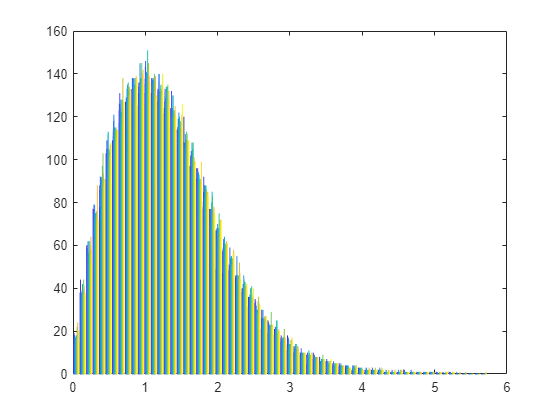

% plot(gauss_out(1,:))
% plot(gauss_hist(1,:))
hist(abs(gauss_d),64)


%generate K=0.5 samples
a = 0.5;
K0_5_d = ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, a, b);
K0_5_order = order_stats(abs(K0_5_d),order_count);
K0_5_mean = mean(abs(K0_5_d),2);
K0_5_std = std(abs(K0_5_d),0,2);
% % K0_5_mean2 = mean(K0_5_d,2);
% % K0_5_std2 = std(K0_5_d,0,2);
K0_5_hist = histc(abs(K0_5_d),range,2)

K0_5_hist =            0           1           2           6           6           9          10          16          20          20          10          16          16          23          22          26          18          33          33          29          27          35          36          33          34          51          46          44          39          43          52          46          42          45          52          43          65          52          66          49          53          62          48          72          50          64          61          58          64          63
           1         807        1738        1531         715         175          32           1           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0   

% figure(2)
% hist(abs(K0_5_d),64) 
% K0_5_out = cat(3, real(K0_5_d),imag(K0_5_d));
K0_5_out = cat(2,K0_5_order,K0_5_mean,K0_5_std)

K0_5_out =     0.0296    0.1593    0.2160    0.2533    0.3044    0.3513    0.3913    0.4204    0.4536    0.4889    0.5098    0.5372    0.5651    0.5881    0.6182    0.6366    0.6566    0.6745    0.7014    0.7253    0.7407    0.7566    0.7729    0.7882    0.8048    0.8218    0.8421    0.8598    0.8785    0.8950    0.9087    0.9269    0.9440    0.9630    0.9755    0.9937    1.0119    1.0252    1.0409    1.0590    1.0713    1.0832    1.0956    1.1145    1.1250    1.1361    1.1459    1.1638    1.1765    1.1953
    0.0003    0.0053    0.0070    0.0084    0.0098    0.0117    0.0129    0.0139    0.0149    0.0160    0.0170    0.0178    0.0188    0.0195    0.0201    0.0208    0.0215    0.0222    0.0229    0.0237    0.0241    0.0245    0.0250    0.0255    0.0261    0.0268    0.0273    0.0281    0.0286    0.0291    0.0295    0.0301    0.0305    0.0310    0.0318    0.0322    0.0326    0.0330    0.0334    0.0338    0.0342    0.0348    0.0353    0.0356    0.0361    0.0365    0.0369    0.0373    0.03

% plot(K0_5_out(1,:))


%generate K=1.5 samples
a = 1.5;
K1_5_d = ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, a, b);
K1_5_order = order_stats(abs(K1_5_d),order_count);
K1_5_mean = mean(abs(K1_5_d),2);
K1_5_std = std(abs(K1_5_d),0,2);
% K1_5_mean2 = mean(K1_5_d,2);
% K1_5_std2 = std(K1_5_d,0,2);
K1_5_hist = histc(abs(K1_5_d),range,2)

K1_5_hist =      0    10    33    51    60    66    96    94   108   125   151   142   157   171   155   195   174   182   193   169   152   163   170   168   152   157   142   128   139   114   113   106   119    80    81    84    66    77    52    50    39    35    45    33    32    24    23    23    18    15
     0     3     8    14     9    29    22    23    36    42    42    40    43    49    54    52    76    55    72    62    87    75    65    77    93    83    66    98    95    92   110   102    88    93    97    86    99    89    83    77    84    95   109    73    88    78    76    79    84    70
     0     3     2    14    10    15    16    21    14    30    31    36    30    45    45    37    41    41    42    49    64    54    53    63    53    62    62    50    74    67    71    76    70    80    80    65    70    63    80    88    84    71    69    87    66    64    64    63    65    71
     0     0     2     1     2     5     6    14     5    16    10    15    14    17 

% figure(3)
% hist(abs(K1_5_d),64) 
% K1_5_out = cat(3, real(K1_5_d),imag(K1_5_d));
K1_5_out = cat(2,K1_5_order,K1_5_mean,K1_5_std)

K1_5_out =     0.0064    0.0458    0.0676    0.0840    0.0952    0.1082    0.1205    0.1333    0.1458    0.1556    0.1643    0.1720    0.1781    0.1859    0.1948    0.2042    0.2101    0.2192    0.2257    0.2328    0.2395    0.2442    0.2506    0.2582    0.2647    0.2704    0.2760    0.2808    0.2873    0.2911    0.2956    0.3004    0.3057    0.3106    0.3155    0.3213    0.3268    0.3320    0.3380    0.3429    0.3491    0.3534    0.3574    0.3624    0.3660    0.3708    0.3752    0.3786    0.3834    0.3894
    0.0095    0.0939    0.1357    0.1691    0.2035    0.2255    0.2505    0.2681    0.2842    0.3031    0.3198    0.3406    0.3570    0.3740    0.3904    0.4035    0.4176    0.4322    0.4474    0.4621    0.4704    0.4790    0.4931    0.5048    0.5193    0.5306    0.5408    0.5508    0.5611    0.5745    0.5842    0.5955    0.6018    0.6090    0.6215    0.6293    0.6414    0.6509    0.6654    0.6756    0.6840    0.6959    0.7046    0.7129    0.7196    0.7284    0.7366    0.7454    0.75

% plot(K1_5_out(1,:))


%generate K=4.5 samples
a = 4.5;
K4_5_d = ClutterSimNG('K',data_num,1, sample_len*train_samples, rho, a, b);
K4_5_order = order_stats(abs(K4_5_d),order_count);
K4_5_mean = mean(abs(K4_5_d),2);
K4_5_std = std(abs(K4_5_d),0,2);
% K4_5_mean2 = mean(K4_5_d,2);
% K4_5_std2 = std(K4_5_d,0,2);
K4_5_hist = histc(abs(K4_5_d),range,2)

K4_5_hist =      0     0     0     4     2     6     8    11    11    10    13    10    14    11     7    22    14    18    18    30    18    21    19    31    26    22    22    24    30    33    32    30    34    32    20    44    41    37    39    41    38    28    37    35    41    45    52    50    46    36
     0     1     2     9     9     8    10     9    15    10    18    17    12    19    23    23    25    24    38    34    34    41    35    39    37    41    46    40    35    45    43    40    27    45    44    45    52    53    44    44    60    47    53    54    53    59    60    59    60    42
     0     2     1     2     5     4     5     9     5    15    11    14     7    16    17    17    17    27    25    25    19    21    23    24    39    35    28    28    29    35    26    27    34    36    30    44    36    39    40    40    45    37    49    35    35    37    50    41    53    50
     0     1     0     1     3     6     2     3     3     2     5     6     6     6 

% figure(4)
% hist(abs(K4_5_d),64) 
% K4_5_out = cat(3, real(K4_5_d),imag(K4_5_d));
K4_5_out = cat(2,K4_5_order,K4_5_mean,K4_5_std)

K4_5_out =     0.0648    0.2003    0.2682    0.3470    0.3977    0.4517    0.4999    0.5396    0.5671    0.6039    0.6440    0.6769    0.7070    0.7300    0.7639    0.7944    0.8329    0.8524    0.8783    0.8957    0.9238    0.9507    0.9712    0.9977    1.0316    1.0519    1.0655    1.0870    1.1080    1.1235    1.1460    1.1639    1.1819    1.1973    1.2232    1.2485    1.2660    1.2941    1.3129    1.3292    1.3516    1.3641    1.3824    1.3940    1.4079    1.4240    1.4419    1.4616    1.4760    1.5006
    0.0252    0.1379    0.2159    0.2777    0.3238    0.3713    0.4061    0.4432    0.4719    0.5061    0.5313    0.5491    0.5727    0.5963    0.6138    0.6344    0.6542    0.6777    0.6939    0.7133    0.7370    0.7560    0.7717    0.7881    0.8068    0.8287    0.8485    0.8613    0.8824    0.8983    0.9153    0.9378    0.9652    0.9851    1.0003    1.0163    1.0363    1.0519    1.0688    1.0841    1.0963    1.1091    1.1255    1.1434    1.1621    1.1793    1.1932    1.2071    1.21

% plot(K4_5_out(1,:))

mean(abs(gauss_mean-K0_5_mean))

ans = 0.6748

mean(abs(gauss_mean-K1_5_mean))

ans = 0.4884

mean(abs(gauss_mean-K4_5_mean))

ans = 1.3237

mean(abs(K0_5_mean-K1_5_mean))

ans = 0.8870

mean(abs(K0_5_mean-K4_5_mean))

ans = 1.8946

mean(abs(K1_5_mean-K4_5_mean))

ans = 1.2363

[hg_05,pg_05] = ttest2(abs(gauss_d),abs(K0_5_d),'Dim',2);
hcnt_g_05 = mean(hg_05)

hcnt_g_05 = 0.9855

mpg_05=mean(pg_05)

mpg_05 = 0.0061


[hg_15,pg_15] = ttest2(abs(gauss_d),abs(K1_5_d),'Dim',2);
hcnt_g_15 = mean(hg_15)

hcnt_g_15 = 0.9655

mpg_15=mean(pg_15)

mpg_15 = 0.0152


[hg_45,pg_45] = ttest2(abs(gauss_d),abs(K4_5_d),'Dim',2);
hcnt_g_45 = mean(hg_45)

hcnt_g_45 = 0.9970

mpg_45=mean(pg_45)

mpg_45 = 0.0012


[h05_15,p05_15] = ttest2(abs(K0_5_d),abs(K1_5_d),'Dim',2);
hcnt_05_15 = mean(h05_15)

hcnt_05_15 = 0.9925

mp05_15=mean(p05_15)

mp05_15 = 0.0025


[h05_45,p05_45] = ttest2(abs(K0_5_d),abs(K4_5_d),'Dim',2);
hcnt_05_45 = mean(h05_45)

hcnt_05_45 = 0.9980

mp05_45=mean(p05_45)

mp05_45 = 9.6849e-04


[h15_45,p15_45] = ttest2(abs(K1_5_d),abs(K4_5_d),'Dim',2);
hcnt_15_45 = mean(h15_45)

hcnt_15_45 = 0.9865

mp15_45=mean(p15_45)

mp15_45 = 0.0059


rand_g = gauss_d(randperm(size(gauss_d, 1)), :);
[hg_g,pg_g,ci_gg,stat_gg] = ttest2(real(gauss_d(1,:)),real(rand_g(1,:)),'Dim',2)

hg_g = 1

pg_g = 2.0105e-09

ci_gg =     0.0804    0.1583


stat_gg = struct with fields:
    tstat: 6.0025
       df: 9998
       sd: 0.9943


[hg_g2,pg_g2,ci_gg2,stat_gg2] = ttest2(real(gauss_d(2,:)),real(rand_g(1,:)),'Dim',2)

hg_g2 = 0

pg_g2 = 0.0829

ci_gg2 =    -0.0733    0.0045


stat_gg2 = struct with fields:
    tstat: -1.7342
       df: 9998
       sd: 0.9922


[hg_g3,pg_g3,ci_gg3,stat_gg3] = ttest2(real(gauss_d(3,:)),real(rand_g(1,:)),'Dim',2)

hg_g3 = 1

pg_g3 = 0.0436

ci_gg3 =    -0.0776   -0.0011


stat_gg3 = struct with fields:
    tstat: -2.0180
       df: 9998
       sd: 0.9757


hcnt_g_g = mean(hg_g)

hcnt_g_g = 1

mpg_g=mean(pg_g)

mpg_g = 2.0105e-09



rand_05 = K0_5_d(randperm(size(K0_5_d, 1)), :);
[h05_05,p05_05] = ttest2(abs(K0_5_d),abs(rand_05),'Dim',2);
hcnt_05_05 = mean(h05_05)

hcnt_05_05 = 0.9865

mp05_05=mean(p05_05)

mp05_05 = 0.0066


rand_15 = K1_5_d(randperm(size(K1_5_d, 1)), :);
[h15_15,p15_15] = ttest2(abs(K1_5_d),abs(rand_15),'Dim',2);
hcnt_15_15 = mean(h15_15)

hcnt_15_15 = 0.9740

mp15_15=mean(p15_15)

mp15_15 = 0.0111


rand_45 = K4_5_d(randperm(size(K4_5_d, 1)), :);
[h45_45,p45_45] = ttest2(abs(K4_5_d),abs(rand_45),'Dim',2);
hcnt_45_45 = mean(h45_45)

hcnt_45_45 = 0.9515

mp45_45=mean(p45_45)

mp45_45 = 0.0175

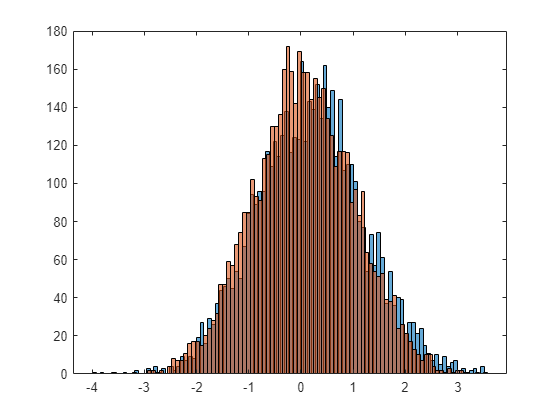

close all
figure(9)
histogram(real(gauss_d(1,:)),100)
hold on
histogram(real(rand_g(1,:)),100)
hold off

[hg_05,pg_05] = ttest2(real(gauss_d),real(K0_5_d),'Dim',2);
hcnt_g_05 = mean(hg_05)

hcnt_g_05 = 0.6545

mpg_05=mean(pg_05)

mpg_05 = 0.1419


[hg_15,pg_15] = ttest2(real(gauss_d),real(K1_5_d),'Dim',2);
hcnt_g_15 = mean(hg_15)

hcnt_g_15 = 0.6545

mpg_15=mean(pg_15)

mpg_15 = 0.1391


[hg_45,pg_45] = ttest2(real(gauss_d),real(K4_5_d),'Dim',2);
hcnt_g_45 = mean(hg_45)

hcnt_g_45 = 0.6415

mpg_45=mean(pg_45)

mpg_45 = 0.1480


[h05_15,p05_15] = ttest2(real(K0_5_d),real(K1_5_d),'Dim',2);
hcnt_05_15 = mean(h05_15)

hcnt_05_15 = 0.6360

mp05_15=mean(p05_15)

mp05_15 = 0.1560


[h05_45,p05_45] = ttest2(real(K0_5_d),real(K4_5_d),'Dim',2);
hcnt_05_45 = mean(h05_45)

hcnt_05_45 = 0.6580

mp05_45=mean(p05_45)

mp05_45 = 0.1425


[h15_45,p15_45] = ttest2(real(K1_5_d),real(K4_5_d),'Dim',2);
hcnt_15_45 = mean(h15_45)

hcnt_15_45 = 0.6505

mp15_45=mean(p15_45)

mp15_45 = 0.1409


rand_g = gauss_d(randperm(size(gauss_d, 1)), :);
[hg_g,pg_g] = ttest2(real(gauss_d),real(rand_g),'Dim',2);
hcnt_g_g = mean(hg_g)

hcnt_g_g = 0.6580

mpg_g=mean(pg_g)

mpg_g = 0.1520


rand_05 = K0_5_d(randperm(size(K0_5_d, 1)), :);
[h05_05,p05_05] = ttest2(real(K0_5_d),real(rand_05),'Dim',2);
hcnt_05_05 = mean(h05_05)

hcnt_05_05 = 0.6380

mp05_05=mean(p05_05)

mp05_05 = 0.1529


rand_15 = K1_5_d(randperm(size(K1_5_d, 1)), :);
[h15_15,p15_15] = ttest2(real(K1_5_d),real(rand_15),'Dim',2);
hcnt_15_15 = mean(h15_15)

hcnt_15_15 = 0.6540

mp15_15=mean(p15_15)

mp15_15 = 0.1388


rand_45 = K4_5_d(randperm(size(K4_5_d, 1)), :);
[h45_45,p45_45] = ttest2(real(K4_5_d),real(rand_45),'Dim',2);
hcnt_45_45 = mean(h45_45)

hcnt_45_45 = 0.6505

mp45_45=mean(p45_45)

mp45_45 = 0.1446

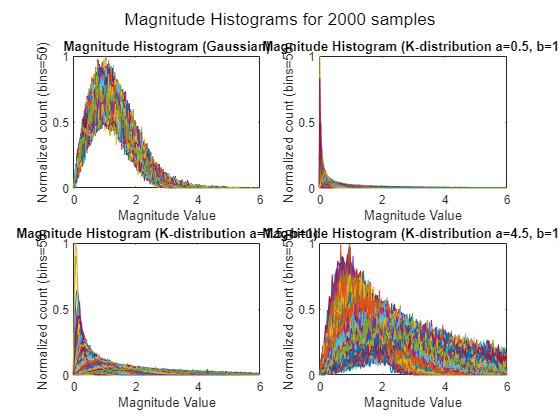

figure(1)
sgtitle('Magnitude Histograms for 2000 samples')
subplot(2,2,1)
plot(range,(gauss_hist./max(max(gauss_hist)))')
title('Magnitude Histogram (Gaussian)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(2,2,2)
plot(range,(K0_5_hist./max(max(K0_5_hist)))')
title('Magnitude Histogram (K-distribution a=0.5, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(2,2,3)
plot(range,(K1_5_hist./max(max(K1_5_hist)))')
title('Magnitude Histogram (K-distribution a=1.5, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')
subplot(2,2,4)
plot(range,(K4_5_hist./max(max(K4_5_hist)))')
title('Magnitude Histogram (K-distribution a=4.5, b=1)')
xlabel('Magnitude Value') 
ylabel('Normalized count (bins=50)')

% index=2
% figure(2)
% plot(range,gauss_hist(index,:), range,K0_5_hist(index,:),range, K1_5_hist(index,:),range,K4_5_hist(index,:))
% legend('guassian','K=0.5','K=1.5','K=4.5')

rand_g_hist = gauss_hist(randperm(size(gauss_hist, 1)), :);
mean(gauss_hist,2);
std(gauss_hist,0,2);
[hg_gh,pg_gh] = ttest2(gauss_hist./max(max(gauss_hist)),rand_g_hist./max(max(rand_g_hist)),'Dim',2);
hcnt_g_gh = mean(hg_gh)

hcnt_g_gh = 0

mpg_gh=mean(pg_gh)

mpg_gh = 1.0000


[hg_05h,pg_05h] = ttest2(gauss_hist./max(max(gauss_hist)),K0_5_hist./max(max(K0_5_hist)),'Dim',2);
hcnt_g_05h = mean(hg_05h)

hcnt_g_05h = 1

mpg_05h=mean(pg_05h)

mpg_05h = 4.6974e-22


[hg_15h,pg_15h] = ttest2(gauss_hist./max(max(gauss_hist)),K1_5_hist./max(max(K1_5_hist)),'Dim',2);
hcnt_g_15h = mean(hg_15h)

hcnt_g_15h = 1

mpg_15h=mean(pg_15h)

mpg_15h = 1.1049e-18


[hg_45h,pg_45h] = ttest2(gauss_hist./max(max(gauss_hist)),K4_5_hist./max(max(K4_5_hist)),'Dim',2);
hcnt_g_45h = mean(hg_45h)

hcnt_g_45h = 0.0100

mpg_45h=mean(pg_45h)

mpg_45h = 0.6961


[h05_15h,p05_15h] = ttest2(K0_5_hist./max(max(K0_5_hist)),K1_5_hist./max(max(K1_5_hist)),'Dim',2);
hcnt_05_15h = mean(h05_15h)

hcnt_05_15h = 0.9995

mp05_15h=mean(p05_15h)

mp05_15h = 1.5470e-04


[h05_45h,p05_45h] = ttest2(K0_5_hist./max(max(K0_5_hist)),K4_5_hist./max(max(K4_5_hist)),'Dim',2);
hcnt_05_45h = mean(h05_45h)

hcnt_05_45h = 1

mp05_45h=mean(p05_45h)

mp05_45h = 1.5960e-20


[h15_45h,p15_45h] = ttest2(K1_5_hist./max(max(K1_5_hist)),K4_5_hist./max(max(K4_5_hist)),'Dim',2);
hcnt_15_45h = mean(h15_45h)

hcnt_15_45h = 1

mp15_45h=mean(p15_45h)

mp15_45h = 7.2104e-18


label=zeros(data_num*3,1);
label(data_num+1:data_num*2,1) = 1;
label(data_num*2+1:data_num*3,1) = 2;

data = cat(1,gauss_out,K0_5_out,K4_5_out)

data =     0.0207    0.1256    0.1704    0.2037    0.2213    0.2573    0.2748    0.2971    0.3206    0.3383    0.3497    0.3700    0.3841    0.4008    0.4148    0.4301    0.4396    0.4537    0.4659    0.4837    0.4954    0.5110    0.5256    0.5337    0.5445    0.5645    0.5730    0.5836    0.5935    0.6065    0.6164    0.6240    0.6395    0.6513    0.6582    0.6676    0.6731    0.6839    0.6961    0.7048    0.7118    0.7191    0.7266    0.7343    0.7430    0.7518    0.7606    0.7699    0.7784    0.7862
    0.0231    0.0994    0.1358    0.1686    0.2050    0.2362    0.2562    0.2716    0.2925    0.3115    0.3267    0.3448    0.3606    0.3732    0.3922    0.4054    0.4198    0.4326    0.4434    0.4575    0.4688    0.4843    0.4939    0.5045    0.5160    0.5282    0.5417    0.5524    0.5614    0.5726    0.5807    0.5893    0.5974    0.6088    0.6170    0.6299    0.6387    0.6505    0.6601    0.6674    0.6774    0.6859    0.6942    0.7026    0.7115    0.7236    0.7329    0.7401    0.7491  

% 
save('clutter_order_3.mat','data', 'label')


function [rank_x] = order_stats(x,k)
[n1,n2]=size(x);
sort_x = sort(x,2);
rank_x = zeros(n1,k);
span=(n2-1)/(k-1);
spans = 0:1:(k-1);
set_span = int64(spans*span+1);
for i=1:k
    rank_x(:,i)=sort_x(:,set_span(i));
end
end